%gram-schmit orthogonaliazation 
V= [1 0 0; 1 1 1; 0 0 1]';
num_vectors = size(V, 2);
U= zeros(size(V));
E= zeros(size(V));
U(:,1)=V(:,1); 
E(:,1)=U(:,1)/norm(U(:,1)); 
for i = 2:num_vectors
U(:,i) = V(:,i);
for j = 1:i-1
U(:,i)=U(:,i)-(dot(V(:,i),E(:,j))*E(:,j)); 
end
E(:,i)=U(:,i)/norm(U(:,i)); 
end
disp('Orthonormal basis vectors:');

Orthonormal basis vectors:


disp(E);

    1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071



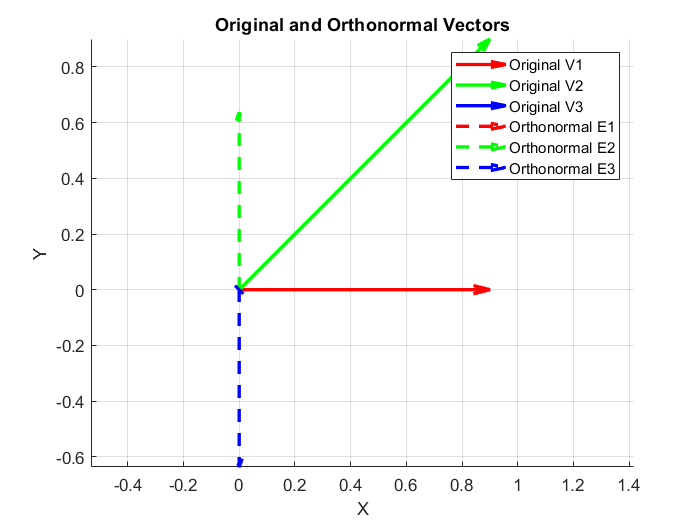

figure;
hold on;
grid on;
axis equal;
quiver3(0,0,0,V(1,1),V(2,1),V(3,1), 'r', 'LineWidth', 2);
quiver3(0,0,0,V(1,2),V(2,2),V(3,2), 'g', 'LineWidth', 2);
quiver3(0,0,0,V(1,3),V(2,3),V(3,3), 'b', 'LineWidth', 2);
quiver3(0,0,0, E(1,1), E(2,1), E(3,1), 'r--', 'LineWidth', 2);
quiver3(0,0,0, E(1,2), E(2,2), E(3,2), 'g--', 'LineWidth', 2);
quiver3(0,0,0, E(1,3), E(2,3), E(3,3), 'b--', 'LineWidth', 2);
xlabel('X');
ylabel('Y');
zlabel('Z');
legend('Original V1', 'Original V2', 'Original V3', 'Orthonormal E1', 'Orthonormal E2', 'Orthonormal E3');
title('Original and Orthonormal Vectors');
hold off;